# **R-factor: link of 4D seismic and PDA**

## Introduction

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

## Create simple VTI model

Reservoir properties: 

Bulk density [kg/m3] 2700

Bulk modulus [GPa] 6

Shear modulus [Gpa]] 1

Tensile strength [Mpa] 1.6

Shear stress [MPa] 5.7

Porosity typically ranges from 10 to 24%

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

Results = MLD('/home/ivan/Desktop/Comsol/My_model_4_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_4_G_file.mat');



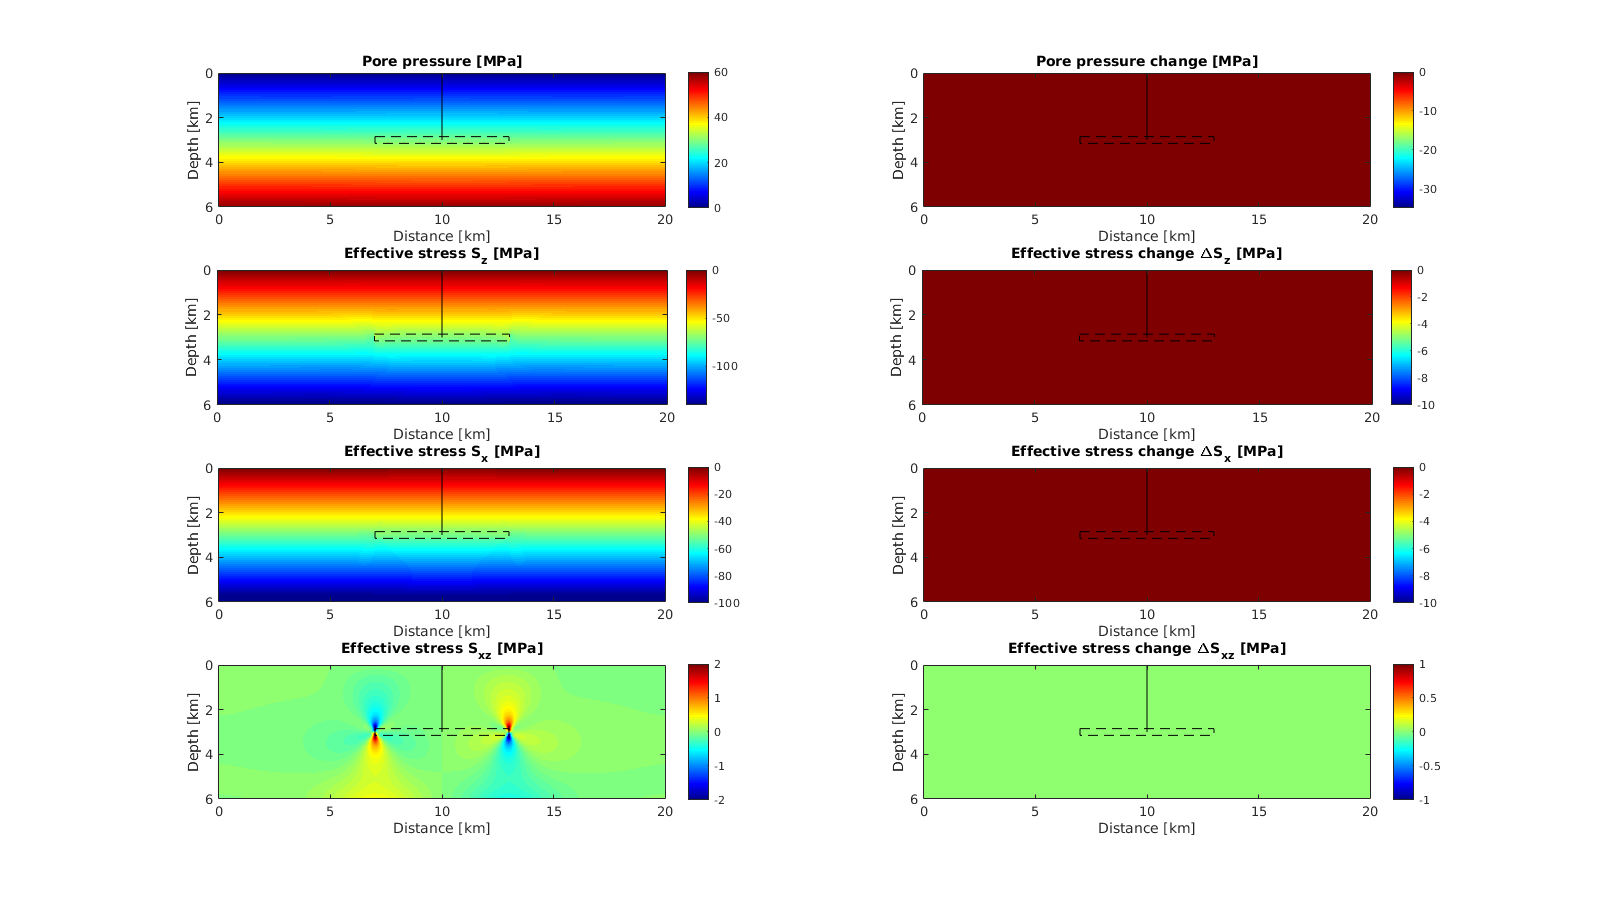

     1



     2



loops = 101;
F(loops) = struct('cdata',[],'colormap',[]);


for tt = 1:1:101 

    figure(223)
    fig = figure('Position', [1 1 1600 900]);
    subplot(4,2,1)
    imagesc(G.xx/1e3, G.zz/1e3, Results.pressure(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Pore pressure [MPa]')
    caxis([0 60])
    
    subplot(4,2,3)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_y(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress S_z [MPa]')
    caxis([-140 0])
    
    subplot(4,2,5)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_x(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress S_x [MPa]')
    caxis([-100 0])
    
    subplot(4,2,7)
    imagesc(G.xx/1e3, G.zz/1e3, Results.stress_xy(:,:,tt)'/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress S_{xz} [MPa]')
    caxis([-2 2])
    
    subplot(4,2,2)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.pressure(:,:,tt)'-Results.pressure(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Pore pressure change [MPa]')
    caxis([-35 0])
    
    subplot(4,2,4)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_y(:,:,tt)'-Results.stress_y(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress change \DeltaS_z [MPa]')
    caxis([-10 0])
    
    subplot(4,2,6)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_x(:,:,tt)'-Results.stress_x(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress change \DeltaS_x [MPa]')
    caxis([-10 0])
    
    subplot(4,2,8)
    imagesc(G.xx/1e3, G.zz/1e3, (Results.stress_xy(:,:,tt)'-Results.stress_xy(:,:,1)')/1e6)
    hold on 
    rectangle('Position', [7.0,2.85,6,0.3], 'LineStyle',  '--')
    plot(linspace(10,10,101),linspace(0,3,101),'k-')
    colormap jet
    colorbar
    axis('equal')
    axis([0 20 0 6])
    xlabel('Distance [km]')
    ylabel('Depth [km]')
    title('Effective stress change \DeltaS_{xz} [MPa]')
    caxis([-1 1])

    F(tt) = getframe(gcf);
    pause(0.03);
    disp(tt)
%    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

end

## Save Movie

v = VideoWriter('/home/ivan/Desktop/test','Motion JPEG AVI');
open(v);
writeVideo(v,F);
close(v);